# MANYPREDICTORS

Fit and evaluate a multivariate linear model with and without outlier weighting.

## Load data

load carEcon

## Fit a multivariate linear model of fuel economy

mdl = fitlm(carTrain);

## Evaluate model at test predictor values

econpred = predict(mdl,carTest);

## Compare predicted and actual responses

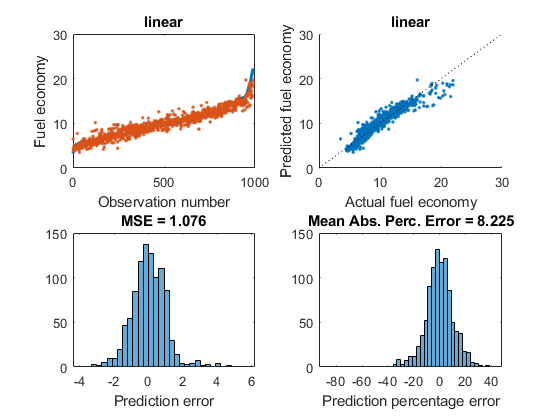

evaluatefit(carTest.FuelEcon,econpred,'linear')

## Fit and evaluate a multivariate linear model with robust fitting

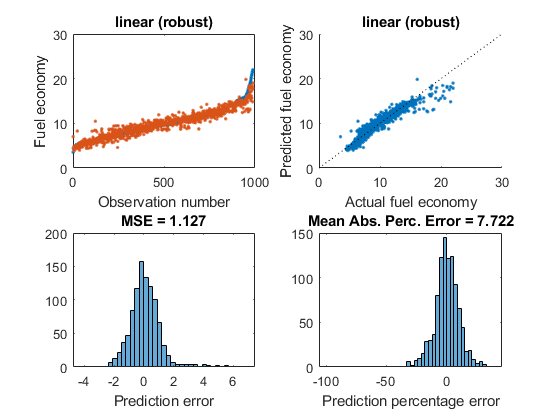

mdl = fitlm(carTrain,'RobustOpts','cauchy');
econpred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econpred,'linear (robust)')